# 线6-35mm线麦导向向量、各角度的相关性查看

#### 载入导向向量

clc;clearvars; close all;
thetaRange = 0:5:180;
load A.mat
[micNum,thetaNum,binNum] = size(steerMatrix);

micSelect = 3 ;

#### 调节频率

theta =90;
disp(['target is at ',num2str(theta),' degree'])

target is at 90 degree


P = zeros(binNum,thetaNum);
for ii = 1:binNum
    for jj = 1:thetaNum
        idx = find(thetaRange==theta);
        W = steerMatrix(1:micSelect,idx,ii);
        b = steerMatrix(1:micSelect,jj,ii);
        P(ii,jj) = abs(W'*b)/micSelect;
    end
end

#### 绘图

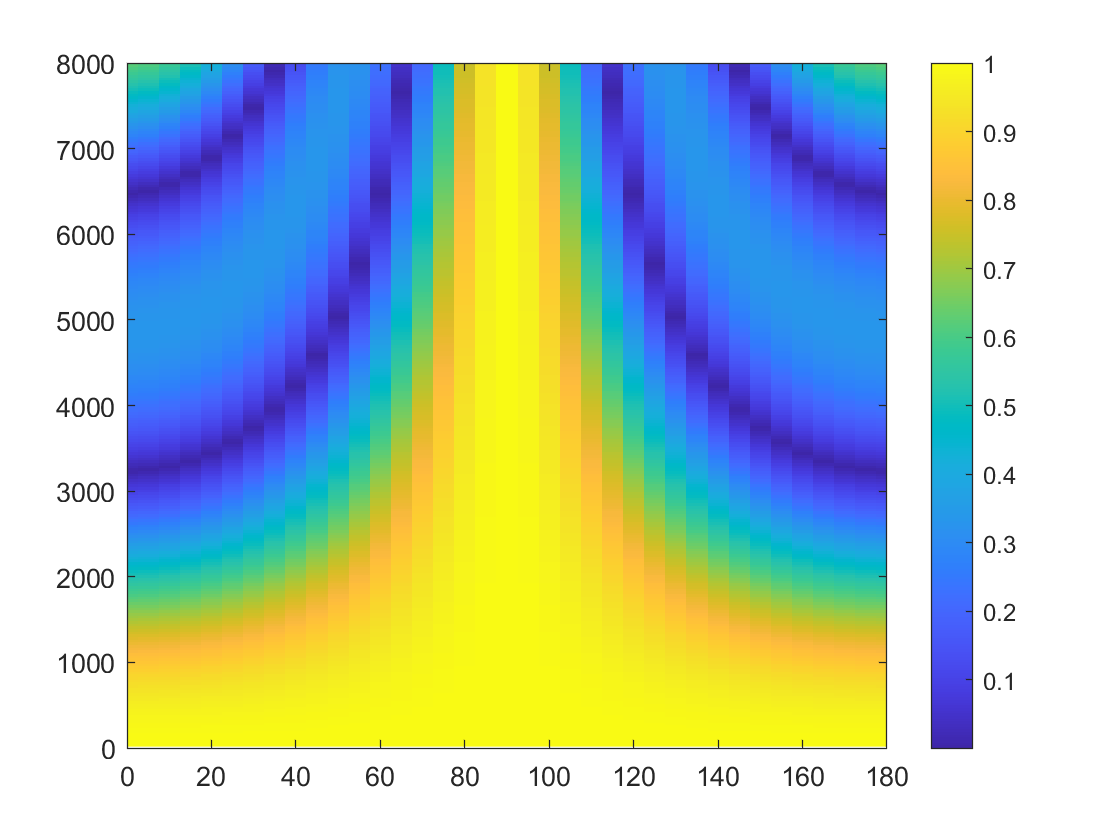

imagesc(thetaRange,(1:binNum)*8000/(binNum-1),P);colorbar;
xlim([0,180]);ylim([0,8000]);axis xy